# Experiment 1_2

### Group members: 

Arman Miraghasi Khani - 40023080

Tina Shariatzadeh - 40023043

Parsa Salehi - 40023048

### clear workspace

clc;
clear;
close all;

## Part 6: aliasing in time domein

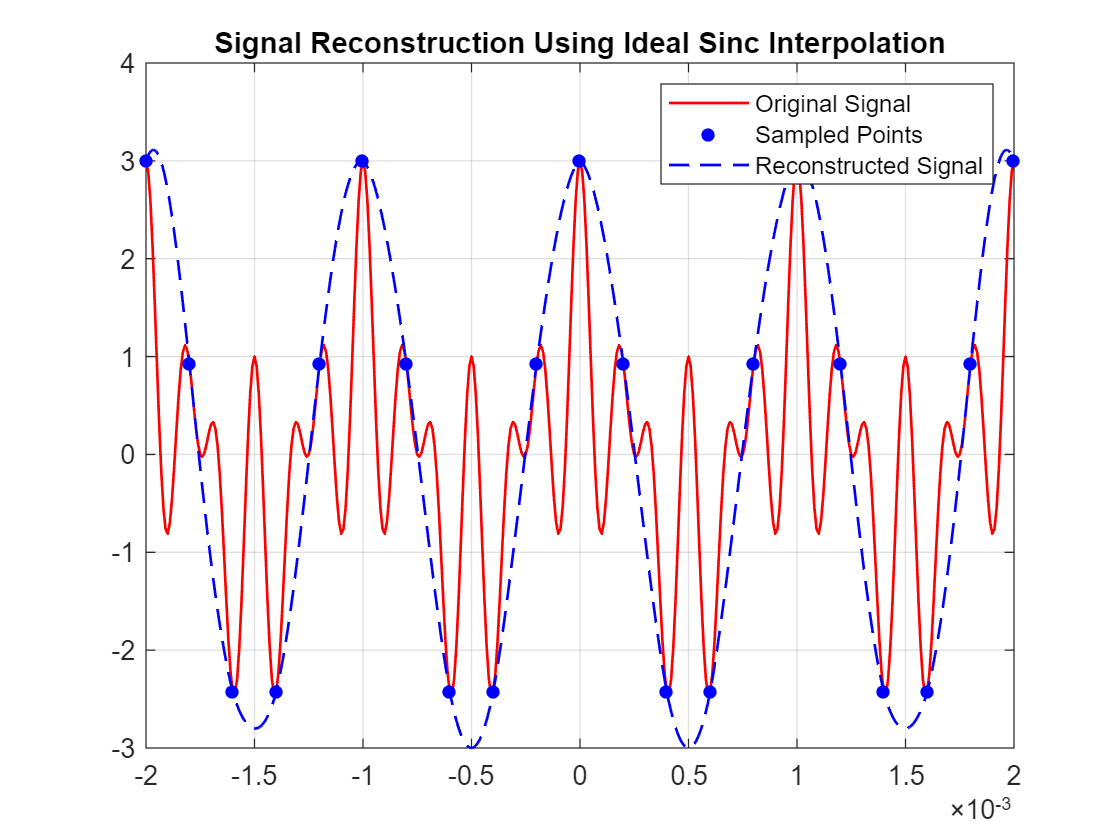

Ts = 0.00001;
t = -0.002:Ts:0.002;
x = cos(2*pi*1e3*t) + cos(8*pi*1e3*t) + cos(12*pi*1e3*t);
figure("Name", "original signal");
plot(t, x, LineWidth=1, Color='r');
title("original signal with samples");
hold on;
fs_low = 5e3;
T_low = 1/fs_low;
t_sampled = -0.002:1/fs_low:0.002;
x_sampled = cos(2*pi*1e3*t_sampled) + cos(8*pi*1e3*t_sampled) + cos(12*pi*1e3*t_sampled);
plot(t_sampled, x_sampled, '.b', 'MarkerSize', 15);

prc_rate = 100; 
t_oversampled = -0.002:1/(prc_rate * fs_low):0.002; 

x_oversampled = zeros(1, length(t_oversampled));
sampled_indices = 1:prc_rate:length(t_oversampled); 
x_oversampled(sampled_indices) = x_sampled; 

h = sinc(fs_low * t_oversampled); 

x_reconstructed = conv(x_oversampled, h, 'same'); 

plot(t_oversampled, x_reconstructed, '--b', 'LineWidth', 1); 
legend('Original Signal', 'Sampled Points', 'Reconstructed Signal');
title("Signal Reconstruction Using Ideal Sinc Interpolation");
grid on;

I expected that reconstructed signal would be a signal with lower frequency. Expectation was true as we can see in the figure above. It is because we didn't take enough samples from our signal and we have aliasing. Sampling rate is 5KHz which is lower than 2BW=12KHz.

## Part 7: aliasing in frequency domein (part 1)

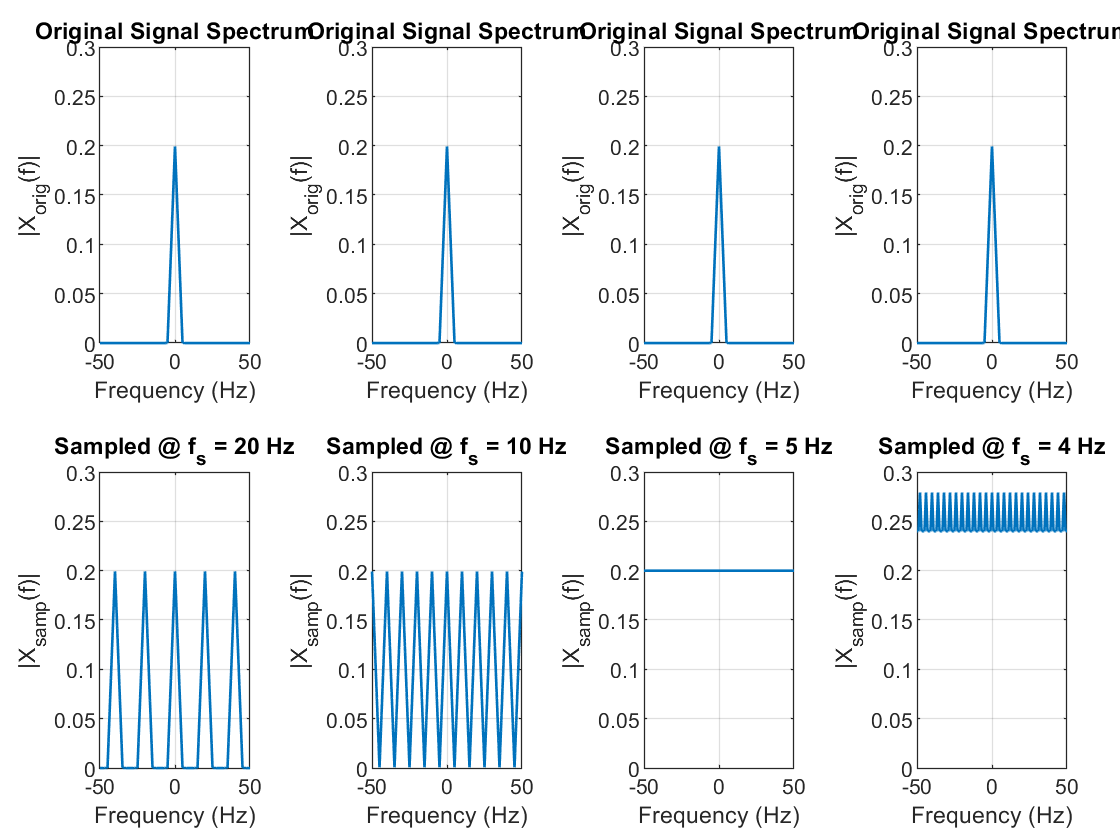

Fs_ct = 100;
dt = 1/Fs_ct;
t = -5:dt:5;
x_t = (sinc(5*t)).^2;

N_ct = length(x_t);
X_t = fftshift(fft(x_t)) * dt;
freq_ct = linspace(-Fs_ct/2, Fs_ct/2, N_ct);

Nfft = 2048;
fs_list = [20, 10, 5, 4];
freq_range = [-50, 50];

figure('Name','Spectra of x(t) and Sampled Versions');
tiledlayout(2,4, 'Padding','compact');

for k = 1:4
    nexttile(k);
    plot(freq_ct, abs(X_t), 'LineWidth', 1);
    xlim(freq_range);
    ylim([0, 0.3]);
    xlabel('Frequency (Hz)');
    ylabel('|X_{orig}(f)|');
    title('Original Signal Spectrum');
    grid on;
end

for i = 1:length(fs_list)
    fs = fs_list(i);
    Ts = 1/fs;
    t_s = -5:Ts:5;
    x_s = (sinc(5*t_s)).^2;

    X_samp = fftshift(fft(x_s, Nfft)) * Ts;
    freq_1z = linspace(-fs/2, fs/2, Nfft);

    min_freq = freq_range(1);
    max_freq = freq_range(2);
    num_rep = ceil((max_freq - min_freq) / fs / 2);

    freq_rep = [];
    X_rep = [];
    for m = -num_rep:num_rep
        freq_rep = [freq_rep, freq_1z + m*fs];
        X_rep = [X_rep, abs(X_samp)];
    end

    nexttile(i + 4);
    plot(freq_rep, X_rep, 'LineWidth', 1);
    xlim(freq_range);
    ylim([0, 0.3]);
    xlabel('Frequency (Hz)');
    ylabel('|X_{samp}(f)|');
    title(sprintf('Sampled @ f_s = %d Hz', fs));
    grid on;
end

## Part 8: aliasing in frequency domein (part 2)

## Part 9: multi-rate filter banks

### a) calculating fft of a signal

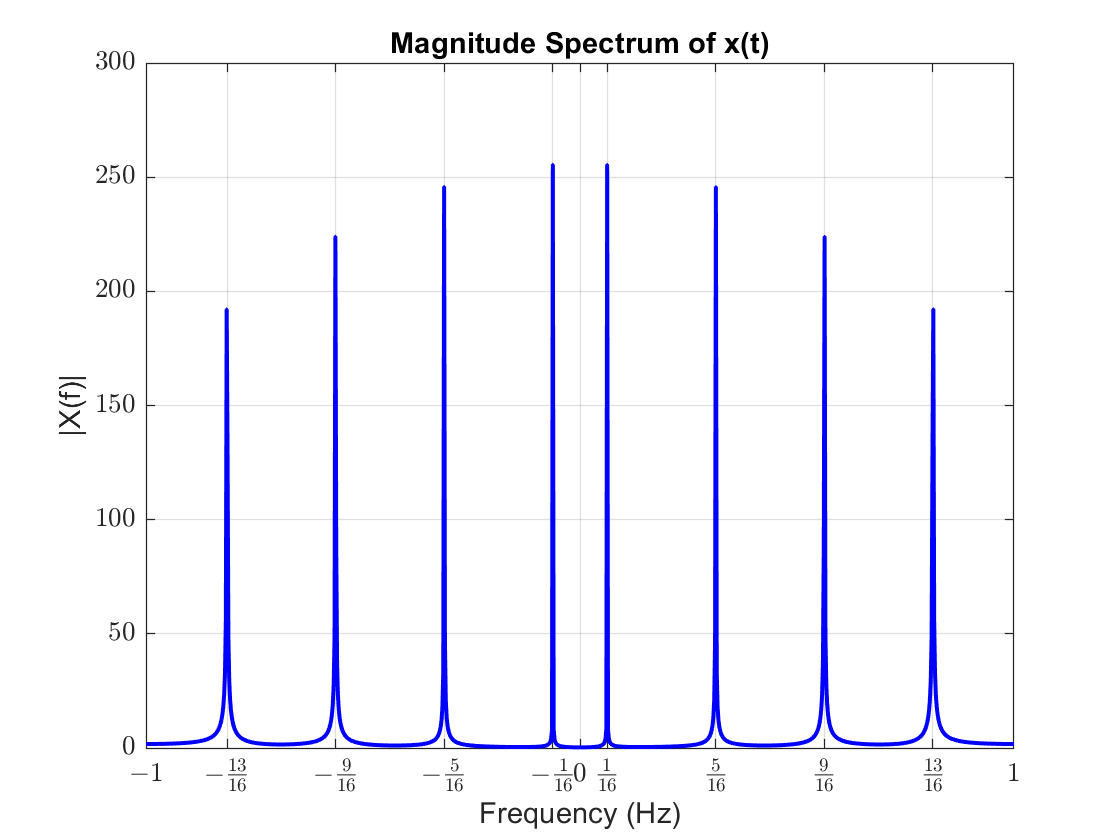

fs = 2;
Ts = 1/fs;
t = 0:Ts:511;
x = cos(2*pi*(1/16)*t) + cos(2*pi*(5/16)*t) + cos(2*pi*(9/16)*t) + cos(2*pi*(13/16)*t);
FT_x = Ts * fftshift(fft(x));

fs = 1/Ts; 
f = linspace(-fs/2, fs/2, length(FT_x)); 

figure("Name", "Frequency Domain");
plot(f, abs(FT_x), 'LineWidth', 1.5, 'Color', 'b');
xlabel("Frequency (Hz)");
ylabel("|X(f)|");
title("Magnitude Spectrum of x(t)");
grid on;
xlim([-1 1]);
xticks([-1, -13/16, -9/16, -5/16, -1/16, 0, 1/16, 5/16, 9/16, 13/16, 1]);
xticklabels({'$-1$', '$-\frac{13}{16}$', '$-\frac{9}{16}$', '$-\frac{5}{16}$', ...
             '$-\frac{1}{16}$', '$0$', '$\frac{1}{16}$', '$\frac{5}{16}$', ...
             '$\frac{9}{16}$', '$\frac{13}{16}$', '$1$'});
set(gca, 'TickLabelInterpreter', 'latex'); % Enable LaTeX formatting

### b) import coefficients of analysis and synthesis filters from a xls file

analysis_filters = readmatrix("experiment_1_2\filters.xls", "Sheet", "Sheet1");

Error using readmatrix (line 158)
Unable to find or open 'experiment_1_2\filters.xls'. Check the path and filename or file permissions.

synthesis_filters = readmatrix("experiment_1_2\filters.xls", "Sheet", "Sheet2");
figure('Name', "Amplitiude of frequency response of digital filters");

for i = 1:4
    n = 0:32 - 1;
    [H, w_axis] = freqz(analysis_filters(i, :), 1, 100);
    subplot(4, 2, 2 * i -1);
    plot(w_axis / pi, abs(H), 'LineWidth', 1.5);
    xlabel('Normalized Frequency');
    ylabel('Magnitude');
    xlim([0 1]);
    title(strcat("Frequency response of analysis filter ", string(i)));
    grid on;

    [H, w_axis] = freqz(synthesis_filters(i, :), 1, 100);
    subplot(4, 2, 2 * i);
    plot(w_axis / pi, abs(H), 'LineWidth', 1.5);
    xlabel('Normalized Frequency');
    ylabel('Magnitude');
    xlim([0 1]);
    title(strcat("Frequency response of synthesis filter ", string(i)));
    grid on;
end
figure('Name', "Phase of frequency response of digital filters");

for i = 1:4
    [H, w_axis] = freqz(analysis_filters(i, :), 1, 1024);
    subplot(4, 2, 2 * i -1);
    plot(w_axis / pi, angle(H), 'LineWidth', 1.5);
    xlabel('Normalized Frequency');
    ylabel('Phase');
    xlim([0 1]);
    title(strcat("Frequency response of analysis filter ", string(i)));
    grid on;

    [H, w_axis] = freqz(synthesis_filters(i, :), 1, 1024);
    subplot(4, 2, 2 * i);
    plot(w_axis / pi, angle(H), 'LineWidth', 1.5);
    xlabel('Normalized Frequency');
    ylabel('Phase');
    xlim([0 1]);
    title(strcat("Frequency response of synthesis filter ", string(i)));
    grid on;

end

### c) processing on frequency bands and plotting the result

%% first method
% x1 = downsample(conv(x, analysis_filters(1,:), "same"), 4);
% x2 = downsample(conv(x, analysis_filters(2,:), "same"), 4);
% x3 = downsample(conv(x, analysis_filters(3,:), "same"), 4);
% x4 = downsample(conv(x, analysis_filters(4,:), "same"), 4);
%% second method
x1 = downsample(filter(analysis_filters(1,:), 1, x), 4);
x2 = downsample(filter(analysis_filters(2,:), 1, x), 4);
x3 = downsample(filter(analysis_filters(3,:), 1, x), 4);
x4 = downsample(filter(analysis_filters(4,:), 1, x), 4);

processed_x1 = 2 .* x1;
processed_x2 = 0 .* x2;
processed_x3 = x3;
processed_x4 = 0.5 .* x4;

%% first method
% reconstructed_x1 = conv(upsample(processed_x1, 4), synthesis_filters(1,:), "same");
% reconstructed_x2 = conv(upsample(processed_x2, 4), synthesis_filters(2,:), "same");
% reconstructed_x3 = conv(upsample(processed_x3, 4), synthesis_filters(3,:), "same");
% reconstructed_x4 = conv(upsample(processed_x4, 4), synthesis_filters(4,:), "same");
%% second method
reconstructed_x1 = filter(synthesis_filters(1,:), 1, upsample(processed_x1, 4));
reconstructed_x2 = filter(synthesis_filters(2,:), 1, upsample(processed_x2, 4));
reconstructed_x3 = filter(synthesis_filters(3,:), 1, upsample(processed_x3, 4));
reconstructed_x4 = filter(synthesis_filters(4,:), 1, upsample(processed_x4, 4));

y = reconstructed_x1 + reconstructed_x2 + reconstructed_x3 + reconstructed_x4;

FT_y = fftshift(fft(y)) / fs;
f1 = linspace(-fs/2, fs/2, length(FT_y)); 

figure("Name", "Frequency Domain");
plot(f, abs(FT_x), 'b', 'LineWidth', 1.5);
hold on;
plot(f1, abs(FT_y), '--g', 'LineWidth', 1.5);
xlabel("Frequency (Hz)");
ylabel("amplitude");
title("Spectrum of input Signal vs output Signal");
legend('Spectrum of input Signal', 'Spectrum of output Signal');
grid on;
xlim([-1 1]);
xticks([-1, -13/16, -9/16, -5/16, -1/16, 0, 1/16, 5/16, 9/16, 13/16, 1]);
xticklabels({'$-1$', '$-\frac{13}{16}$', '$-\frac{9}{16}$', '$-\frac{5}{16}$', ...
             '$-\frac{1}{16}$', '$0$', '$\frac{1}{16}$', '$\frac{5}{16}$', ...
             '$\frac{9}{16}$', '$\frac{13}{16}$', '$1$'});
set(gca, 'TickLabelInterpreter', 'latex'); % Enable LaTeX formatting